# Shaft Design

Malik Labban, Jet Burginger, Isaac Coello Dantus, Allistair Pocock, Anthony Jakubczyk

### Shaft Specs

Nf = 2.5;     % Shaft without stress concentration
Ny = 2.5;     % Shaft without stress concentration
Nf_fillet = 2;% Design factor of fillet with stress concentrations
Ny_fillet = 2;

### Material

rho = 0.284; %lb/in^3
% Sy;   %Define in shaft object
% Sut;  %Define in shaft object

### External Loadings

K = 3;     % Possible load multiplier
Ti = 38.6;  % ft-lbs
RPM = 200;  % RPM unused, infinite life assumed

### Gear Specs

globe.phi_n = deg2rad(20); % deg       (normal pressure angle)
globe.P = 10;     % teeth/in  (normal diametral pitch)
globe.psi = deg2rad(0);   % deg       (helix angle)
scale = 1;
N1 = 67*scale;    % # teeth 
N2 = 16*scale;    % # teeth
N3 = 67*scale;    % # teeth
N4 = 16*scale;
T2 = Ti*N2/N1;
T3 = T2*N4/N3;
% Face width 1.3
%gear# = Gear(globe,name,#teeth,torque on shaft,RPM,pos)

### Shaft Opt

Input Shaft

syms x D
gear1 = Gear(globe,'G1',N1,Ti,RPM,5.45);
bearing1 = bearing('A',4.4);
bearing2 = bearing('B',6.7);
input1 = [0,D; ...   % shaft diamter breakdown
            4,D;     % Bearing 0.8
            4.8,D*1.2;%Gear 
            6.3,D]; % Bearing
geo1 = geo(7.1); % length of shaft
geo1.input = input1;
shaftA = shaft(geo1,'Input Shaft',1000);
shaftA.gear = gear1;
shaftA.bearing = [bearing1,bearing2];
shaftA.presolve(K);
shaftA.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 2.5703$$

$$nymin = 2.5937$$

Minimum diameter for Yielding, 1.8000, for Fatigue, 2.5500.
Initial Diameter 2.5500



shaftA.optimize();

Iteration for fillet radius at point 4.000 is complete, Radi of fillet is 0.000 
This fillet radi had an r/d ratio of 0.000 and h/r of NaN

Iteration for fillet radius at point 4.800 is complete, Radi of fillet is 0.993 
This fillet radi had an r/d ratio of 0.276 and h/r of 0.363

Iteration for fillet radius at point 6.300 is complete, Radi of fillet is 0.018 
This fillet radi had an r/d ratio of 0.005 and h/r of 20.000

Final Diameter 3.6000
Final Weight: 22.4255

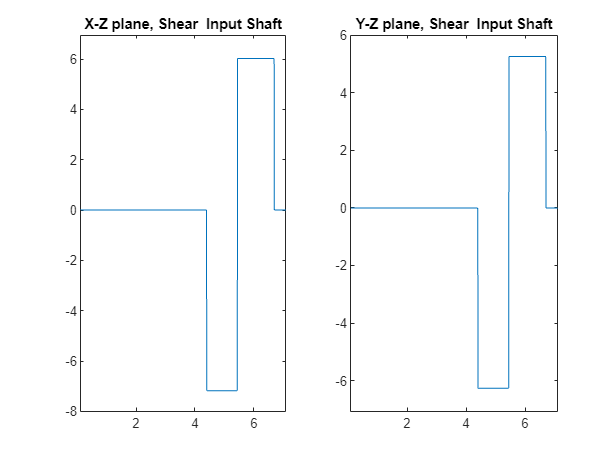

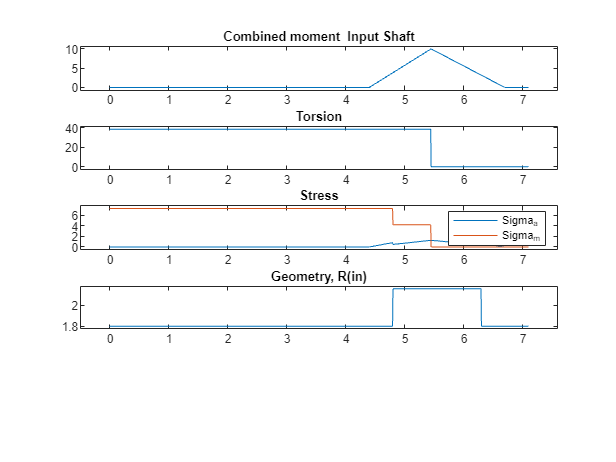

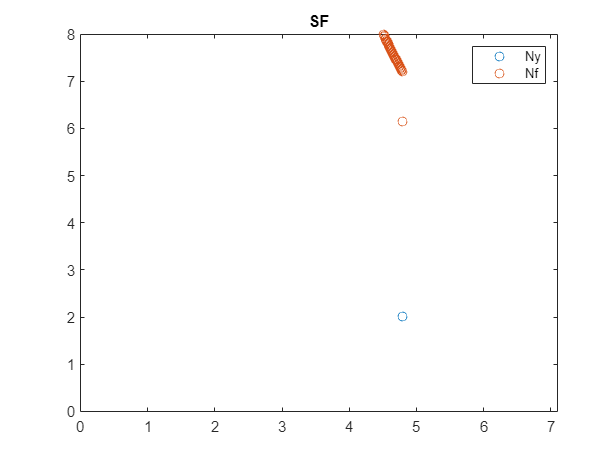

shaftA.plot

### Shaft Opt

Middle Shaft

syms x D
gear2 = Gear(globe,'G2',N2,T2,RPM,1.5);
gear3 = Gear(globe,'G3',N3,T2,RPM,6.9);
bearing3 = bearing('C',0.4);
bearing4 = bearing('D',8);
input2 = [0,D*0.9; ...
            0.8,D*1;
            2.2,D*1.2;
            6.2,D;
            7.6,D*0.9];
geo2 = geo(8.4);
geo2.input = input2;
shaftB = shaft(geo2,'Middle Shaft',1000);
shaftB.gear = [gear2,gear3];
shaftB.bearing = [bearing3,bearing4];
shaftB.presolve(K);
shaftB.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 2.5042$$

$$nymin = 2.5850$$

Minimum diameter for Yielding, 1.3500, for Fatigue, 2.1500.
Initial Diameter 2.1500



shaftB.optimize();

Iteration for fillet radius at point 0.800 is complete, Radi of fillet is 0.007 
This fillet radi had an r/d ratio of 0.003 and h/r of 20.000

Iteration for fillet radius at point 2.200 is complete, Radi of fillet is 0.265 
This fillet radi had an r/d ratio of 0.091 and h/r of 1.096

Iteration for fillet radius at point 6.200 is complete, Radi of fillet is 0.040 
This fillet radi had an r/d ratio of 0.014 and h/r of 7.342

Iteration for fillet radius at point 7.600 is complete, Radi of fillet is 0.007 
This fillet radi had an r/d ratio of 0.003 and h/r of 20.000

Final Diameter 2.9000
Final Weight: 18.4841

shaftB.gear(1).d % Pinion diameter

ans = 1.6000

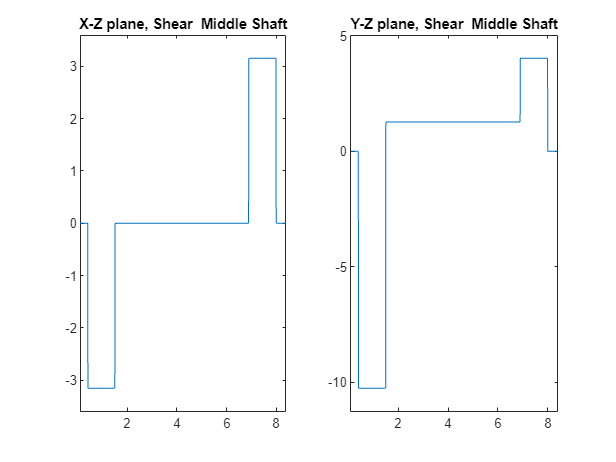

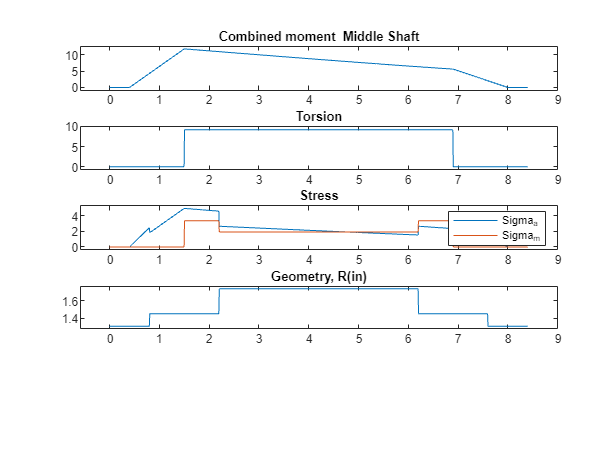

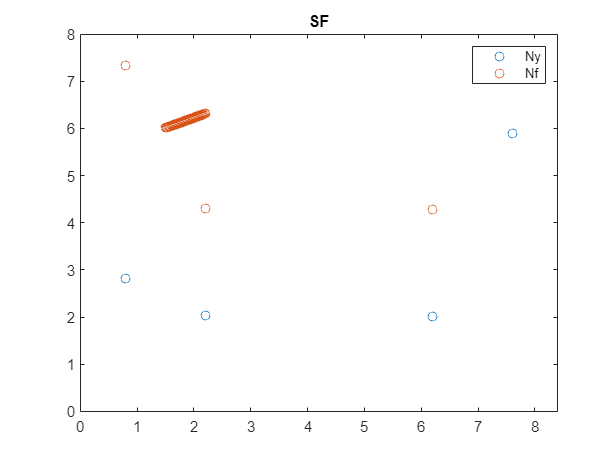

shaftB.plot

### Shaft Opt

Output Shaft

syms x D
gear4 = Gear(globe,'G4',N4,T3,RPM,3.5);
bearing5 = bearing('G',2.4);
bearing6 = bearing('H',4.6);
input3 = [0,D*.9; ...   % shaft diamter breakdown
            2,D;
            2.8,D*1.2;
            4.2,D];
geo3 = geo(5);
geo3.input = input3;
shaftC = shaft(geo3,'Output Shaft',1000);
shaftC.gear = gear4;
shaftC.bearing = [bearing5,bearing6];
shaftC.presolve(K);
shaftC.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 2.6690$$

$$nymin = 5.7214$$

Minimum diameter for Yielding, 1.0000, for Fatigue, 1.1500.
Initial Diameter 1.1500



shaftC.optimize();

Iteration for fillet radius at point 2.000 is complete, Radi of fillet is 0.054 
This fillet radi had an r/d ratio of 0.036 and h/r of 1.524

Iteration for fillet radius at point 2.800 is complete, Radi of fillet is 0.033 
This fillet radi had an r/d ratio of 0.020 and h/r of 4.962

Iteration for fillet radius at point 4.200 is complete, Radi of fillet is 0.008 
This fillet radi had an r/d ratio of 0.005 and h/r of 20.000

Final Diameter 1.6500
Final Weight: 3.1788

shaftC.gear.d % Pinion diameter

ans = 1.6000

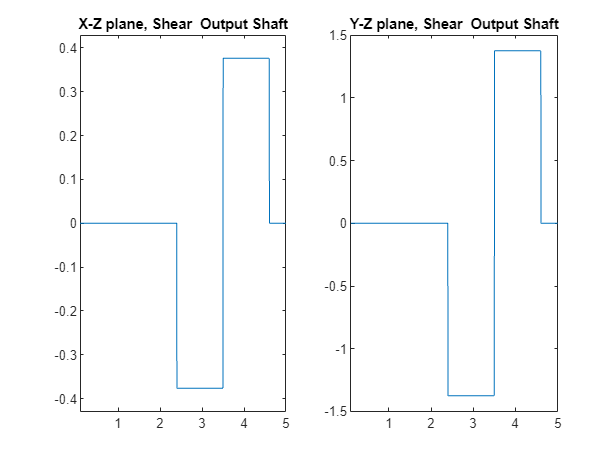

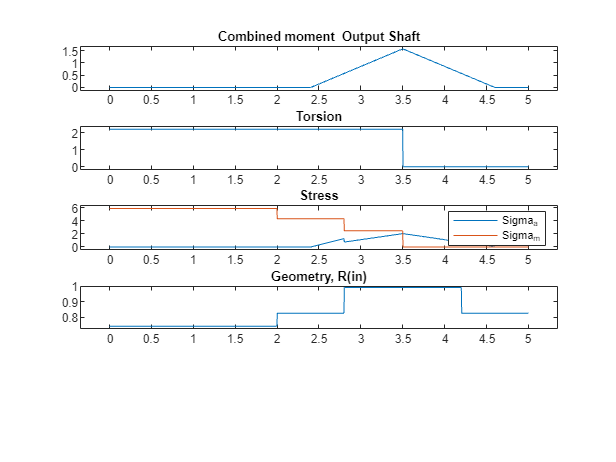

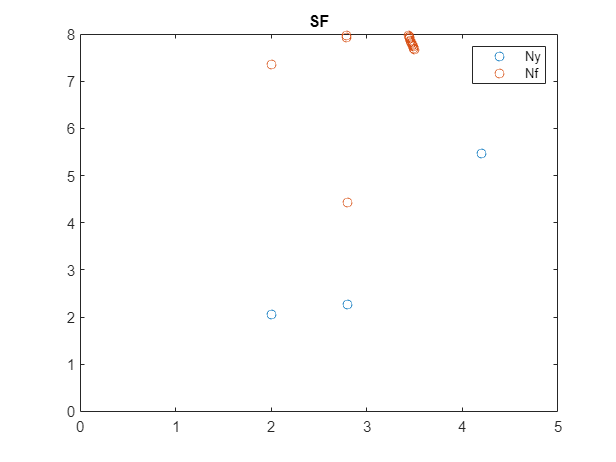

shaftC.plot